irr_vs_fir: script to compare IIR and FIR filters dimensions for similar frequency response.

Version: 001

Date:    2020/04/21

Author:  Rodrigo Gonzalez <rodralez@frm.utn.edu.ar>

URL:     https://github.com/rodralez/td3

URL:     https://github.com/rodralez/control

clc
clear
close all

## FIR design

% fir_kaiser_3400_44100: Low-pass FIR filter, Kaiser window.

Hd_fir = fir_kaiser_3400_44100;

fir_coeff = Hd_fir.coefficients;

## IIR design

% iir_elliptic_3400_44100: funcion que disena un filtro IIR a partir de
% filtro analogico eliptico

Hd_iir = iir_elliptic_3400_44100;

iir_coeff = Hd_iir.coefficients;

## Compare both filters

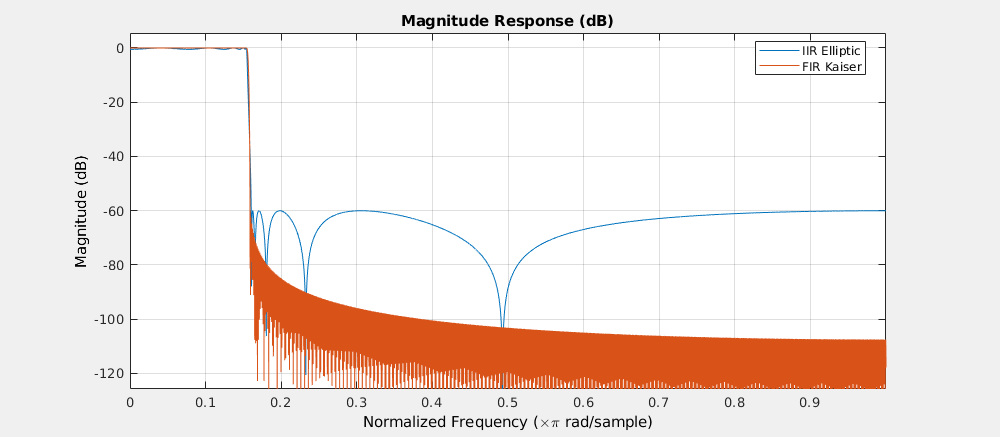

% fvtool: filter visualization tool

hfvt = fvtool(Hd_iir, Hd_fir, 'Analysis','Magnitude');
legend(hfvt,'IIR Elliptic', 'FIR Kaiser')

## Filters dimensions

fir_dim = size(Hd_fir.Numerator);
iir_dim = size(Hd_iir.sosMatrix);

fprintf ('FIR filter dimension is [%d %d]', fir_dim(1), fir_dim(2))

FIR filter dimension is [1 1600]

fprintf ('IIR filter dimension is [%d %d]', iir_dim(1), iir_dim(2))

IIR filter dimension is [5 6]